clear all

% All data uses 100 iterations of 32 x 32 matrices.
% Standard deviation 1
% Error measured in MSE
% E3M4 had massive overflow

buffer_factor = 1.1;

G_5_E = [0.0010926564154215158, 9.86454572994262E-4, 9.86454572994262E-4, 9.86454572994262E-4];
T_5_E = [0.007134590531350114, 0.0069069293985376135, 0.0069069293985376135, 0.0069069293985376135];
G_5_M = [3.0299196775630115, 0.6860931866709143, 0.18573246949585154, 0.05542419784935191, 0.01748063021572307, 0.006223757353145629, 0.0025675346818752587, 0.0011718488251790404];
T_5_M = [35.081853090524675, 10.610810909308492, 2.774156664053444, 0.8561518845730461, 0.269723128604237, 0.06786181908333674, 0.018927082282025366, 0.002500019867438823];

% Some Overflow
G_4_E = [8.38826559484005E-4, 6.82414248585701E-4, 6.82414248585701E-4, 6.82414248585701E-4]; 
T_4_E = [0.0026818021386861802, 0.0025189526751637457, 0.0025189526751637457, 0.0025189526751637457]; 
G_4_M = [4.395390159636736, 0.9962361354008317, 0.19604427132755517, 0.05395969904959202, 0.015786466561257838, 0.004358442723751068, 0.001358387880027294, 5.657585337758064E-4];
T_4_M = [47.80248863238841, 15.116657247766852, 3.6870079901069404, 0.9029697332531214, 0.24758025262504815, 0.08316131744533778, 0.02260719634592533, 0.006297800727188587];

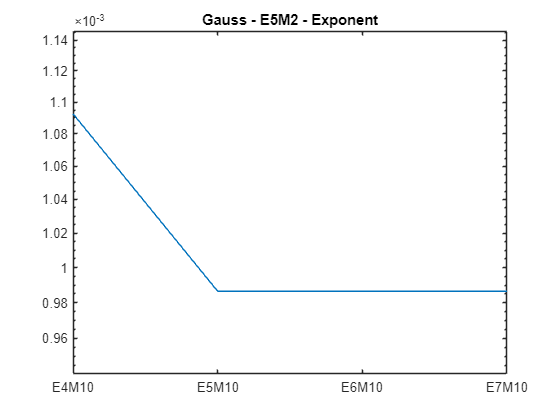

x_values = 1:4; 
custom_labels = {'E4M10', 'E5M10', 'E6M10', 'E7M10'};

semilogy(x_values, G_5_E);

xticks(x_values); 
xticklabels(custom_labels);
%legend("Gaussian", "t-distribution");
auto_ylim = ylim;
ymin_auto = auto_ylim(1);
ymax_auto = auto_ylim(2);

ymin_new = ymin_auto / sqrt(buffer_factor);
ymax_new = ymax_auto * sqrt(buffer_factor);

ylim([ymin_new ymax_new]);

title('Gauss - E5M2 - Exponent');

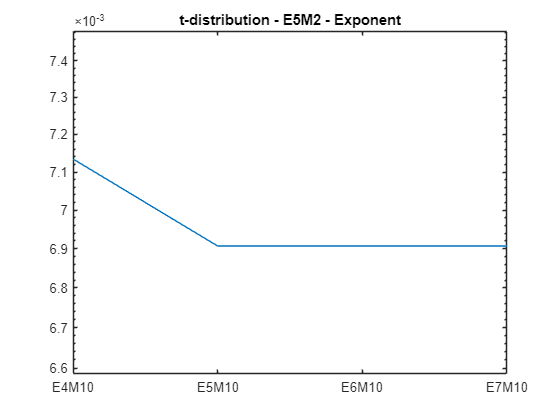

x_values = 1:4; 
custom_labels = {'E4M10', 'E5M10', 'E6M10', 'E7M10'};

semilogy(x_values, T_5_E);

xticks(x_values); 
xticklabels(custom_labels);

auto_ylim = ylim;
ymin_auto = auto_ylim(1);
ymax_auto = auto_ylim(2);

ymin_new = ymin_auto / sqrt(buffer_factor);
ymax_new = ymax_auto * sqrt(buffer_factor);

ylim([ymin_new ymax_new]);

title('t-distribution - E5M2 - Exponent');

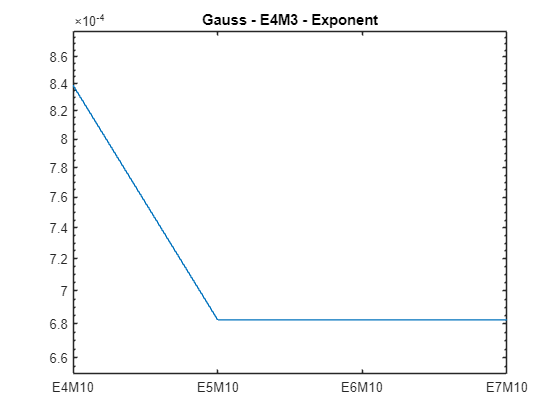

x_values = 1:4; 
custom_labels = {'E4M10', 'E5M10', 'E6M10', 'E7M10'};

semilogy(x_values, G_4_E);

xticks(x_values); 
xticklabels(custom_labels);

auto_ylim = ylim;
ymin_auto = auto_ylim(1);
ymax_auto = auto_ylim(2);

ymin_new = ymin_auto / sqrt(buffer_factor);
ymax_new = ymax_auto * sqrt(buffer_factor);

ylim([ymin_new ymax_new]);

title('Gauss - E4M3 - Exponent');

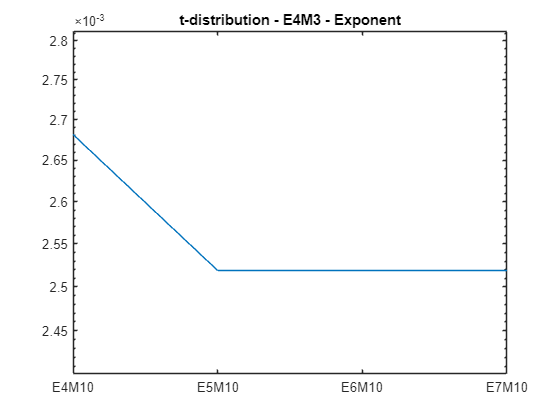

x_values = 1:4; 
custom_labels = {'E4M10', 'E5M10', 'E6M10', 'E7M10'};

semilogy(x_values, T_4_E);

xticks(x_values); 
xticklabels(custom_labels);

auto_ylim = ylim;
ymin_auto = auto_ylim(1);
ymax_auto = auto_ylim(2);

ymin_new = ymin_auto / sqrt(buffer_factor);
ymax_new = ymax_auto * sqrt(buffer_factor);

ylim([ymin_new ymax_new]);

title('t-distribution - E4M3 - Exponent');

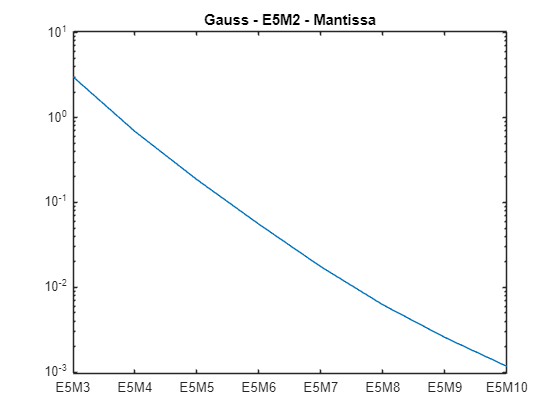

x_values = 1:8; 
custom_labels = {'E5M3', 'E5M4', 'E5M5', 'E5M6', 'E5M7', 'E5M8', 'E5M9', 'E5M10'};

semilogy(x_values, G_5_M);

xticks(x_values); 
xticklabels(custom_labels);
%legend("Gaussian", "t-distribution");
auto_ylim = ylim;
ymin_auto = auto_ylim(1);
ymax_auto = auto_ylim(2);

ymin_new = ymin_auto / sqrt(buffer_factor);
ymax_new = ymax_auto * sqrt(buffer_factor);

ylim([ymin_new ymax_new]);

title('Gauss - E5M2 - Mantissa');

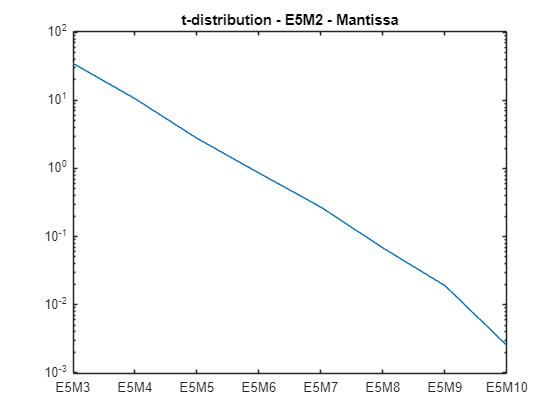

x_values = 1:8; 
custom_labels = {'E5M3', 'E5M4', 'E5M5', 'E5M6', 'E5M7', 'E5M8', 'E5M9', 'E5M10'};

semilogy(x_values, T_5_M);

xticks(x_values); 
xticklabels(custom_labels);

auto_ylim = ylim;
ymin_auto = auto_ylim(1);
ymax_auto = auto_ylim(2);

ymin_new = ymin_auto / sqrt(buffer_factor);
ymax_new = ymax_auto * sqrt(buffer_factor);

ylim([ymin_new ymax_new]);

title('t-distribution - E5M2 - Mantissa');

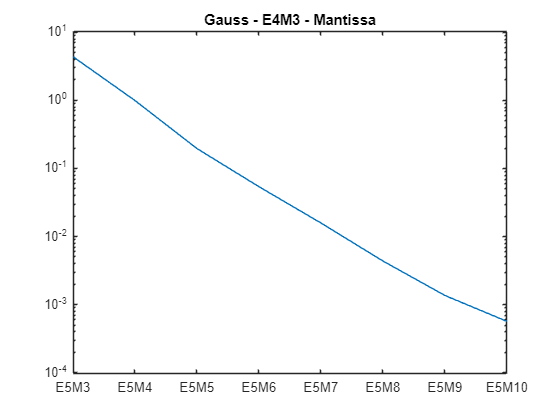

x_values = 1:8; 
custom_labels = {'E5M3', 'E5M4', 'E5M5', 'E5M6', 'E5M7', 'E5M8', 'E5M9', 'E5M10'};

semilogy(x_values, G_4_M);

xticks(x_values); 
xticklabels(custom_labels);

auto_ylim = ylim;
ymin_auto = auto_ylim(1);
ymax_auto = auto_ylim(2);

ymin_new = ymin_auto / sqrt(buffer_factor);
ymax_new = ymax_auto * sqrt(buffer_factor);

ylim([ymin_new ymax_new]);

title('Gauss - E4M3 - Mantissa');

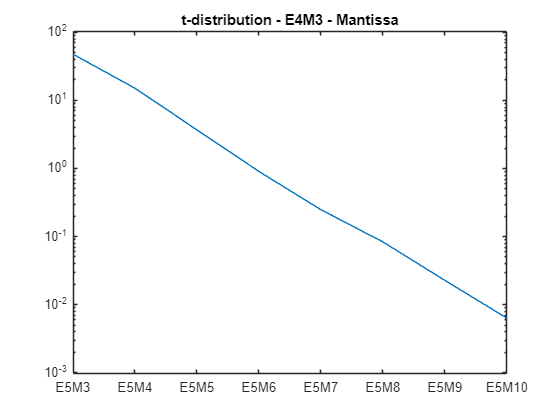

x_values = 1:8; 
custom_labels = {'E5M3', 'E5M4', 'E5M5', 'E5M6', 'E5M7', 'E5M8', 'E5M9', 'E5M10'};

semilogy(x_values, T_4_M);

xticks(x_values); 
xticklabels(custom_labels);

auto_ylim = ylim;
ymin_auto = auto_ylim(1);
ymax_auto = auto_ylim(2);

ymin_new = ymin_auto / sqrt(buffer_factor);
ymax_new = ymax_auto * sqrt(buffer_factor);

ylim([ymin_new ymax_new]);

title('t-distribution - E4M3 - Mantissa');